addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 1: write the linearinterpolation function. 

xs = 1:11;
ys = [850 798 818 903 1026 1042 1022 1069 1070 1135 1096];

splines = linearSpline(xs, ys)

$$splines = \left(\begin{array}{c} 902-52\,x\\ 20\,x+758\\ 85\,x+563\\ 123\,x+411\\ 16\,x+946\\ 1162-20\,x\\ 47\,x+693\\ x+1061\\ 65\,x+485\\ 1525-39\,x \end{array}\right)$$

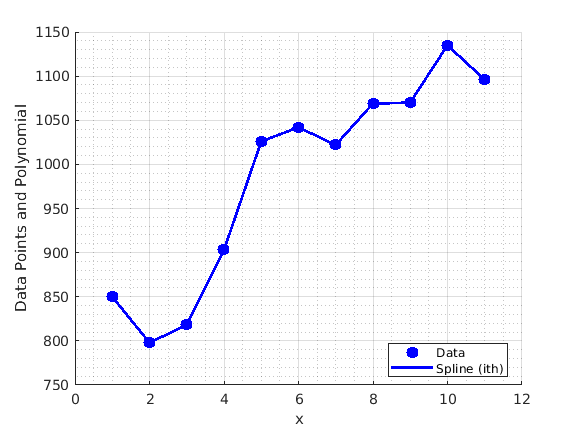

plotSplines(xs, ys, splines)

% estimations
linearinterp = @(xInterps) calcSpline(xs, splines, xInterps)

linearinterp = function_handle with value:
    @(xInterps)calcSpline(xs,splines,xInterps)



% evaluate with sample xx
yy_mine = linearinterp(1:0.1:11) % the sample interpolated values

$$yy\_mine = \left(\begin{array}{ccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 850 & \frac{4224}{5} & \frac{4198}{5} & \frac{4172}{5} & \frac{4146}{5} & 824 & \frac{4094}{5} & \frac{4068}{5} & \frac{4042}{5} & \frac{4016}{5} & 798 & 800 & 802 & 804 & 806 & 808 & 810 & 812 & 814 & 816 & 818 & \frac{1653}{2} & 835 & \frac{1687}{2} & 852 & \frac{1721}{2} & 869 & \frac{1755}{2} & 886 & \frac{1789}{2} & 903 & \frac{9153}{10} & \frac{4638}{5} & \frac{9399}{10} & \frac{4761}{5} & \frac{1929}{2} & \frac{4884}{5} & \frac{9891}{10} & \frac{5007}{5} & \frac{10137}{10} & 1026 & \frac{5138}{5} & \frac{5146}{5} & \frac{5154}{5} & \frac{5162}{5} & 1034 & \frac{5178}{5} & \frac{5186}{5} & \frac{5194}{5} & \frac{5202}{5} & 1042 & 1040 & 1038 & 1036 & 1034 & 1032 & 1030 & 1028 & 1026 & 1024 & 1022 & \frac{10267}{10} & \frac{5157}{5} & \frac{10361}{10} & \frac{5204}{5} & \frac{2091}{2} & \frac{5251}{5} & \frac{10549}{10} & \frac{5298}{5} & \frac{10643}{10} & 1069 & \frac{10691}{10} & \frac{5346}{5} & \frac{10693}{10} & \frac{5347}{5} & \frac{2139}{2} & \frac{5348}{5} & \frac{10697}{10} & \frac{5349}{5} & \frac{10699}{10} & 1070 & \frac{2153}{2} & 1083 & \frac{2179}{2} & 1096 & \frac{2205}{2} & 1109 & \frac{2231}{2} & 1122 & \frac{2257}{2} & 1135 & \frac{11311}{10} & \frac{5636}{5} & \frac{11233}{10} & \frac{5597}{5} & \frac{2231}{2} & \frac{5558}{5} & \frac{11077}{10} & \frac{5519}{5} & \frac{10999}{10} & 1096 \end{array}\right)$$

% estimate
y1 = calcSpline(xs, splines, 3.5)

$$y1 = \frac{1721}{2}$$

y2 = calcSpline(xs, splines, 7.7)

$$y2 = \frac{10549}{10}$$

y3 = calcSpline(xs, splines, 10.1)

$$y3 = \frac{11311}{10}$$

% NOW: plotting the interpolated values above to ensure that they do indeed lie on the straight line segments. 

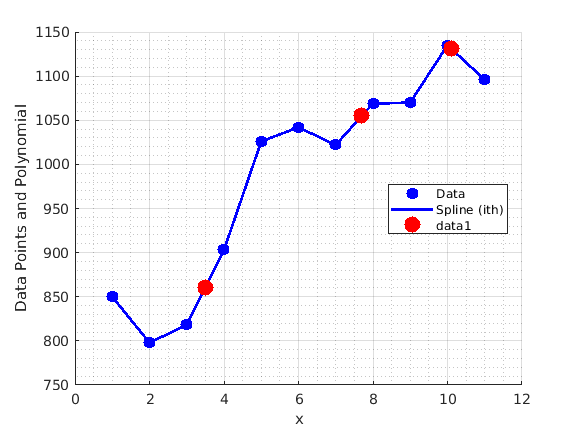

plotSplines(xs, ys, splines)
hold on
plot([3.5 7.7 10.1], [y1, y2, y3], 'r.', 'MarkerSize', 40)

Question 2: compare output to the interp1 function in matlab

yyinterps = interp1(xs, ys, 1:0.1:11, 'linear');
yy_ans = sym(yyinterps);
% compare this with my output
[yy_mine; yy_ans]'

isequal(yy_ans, yy_mine) % THEY ARE EQUAL!!

ans = logical
   1
